load_parameters

t_end = 0.02; % secs - don't change this without changing the chop fraction
t = 0 : t_step : t_end;

power_ratios = logspace(-0.5, 1, 20)

power_ratios =     0.3162    0.3793    0.4549    0.5456    0.6543    0.7848    0.9412    1.1288    1.3539    1.6238    1.9475    2.3357    2.8014    3.3598    4.0296    4.8329    5.7964    6.9519    8.3378   10.0000


taus = tau_res%(:,1);

taus = 	1.0e+-3 *

    0.6902
    0.6897
    0.8808
    0.6897
    0.6902
    0.7639
    0.5012
    0.6765
    0.4982
    0.5410


tau = mean(taus, 2);
reps = 10;

imp_res = zeros([length(power_ratios), reps]);
ratio_res = zeros([length(power_ratios), reps]);
L = length(power_ratios)

L = 20


band_width = 1000

band_width = 1000

band = [f_a-band_width/2, f_a+band_width/2];

parfor rep = 1 : reps
    %rep
    %% generate axion frequency
    f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);
    
    %% generate signal and noise
    signal = generate_axion_signal(t, f_sampling, f_axion, axion_power);
    noise = randn(size(t)); % don't need to scale here, we do that in improvement()

    %% generate axion frequency
    f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);
    
    %% generate signal and noise
    signal = calc_wave_with_frequency(t, f_sampling, f_axion);
    signal = signal / sqrt( bandpower(signal, f_sampling, band) ); % get signal power in band = 1
    noise = randn(size(t));
    noise = noise / sqrt(bandpower(noise, f_sampling, band));

    for i = 1 : L
        signal_in = signal * sqrt(power_ratios(i));
        ratio_res(i, rep) = bandpower(signal_in, f_sampling, band) / bandpower(noise, f_sampling, band)
        
        
        imp_res(i, rep) = imp(tau(i), f_sampling, t, signal, noise, f_a, f_axion, band_width);
        %done = done+1;
        %disp(round(done/(L*reps)*100)), '%')
        disp('done one')
        
    end
end

done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
done one
d

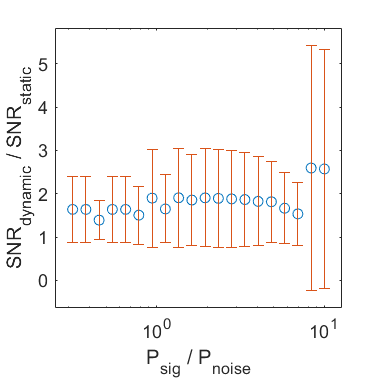

x = mean(ratio_res, 2);
y = mean(imp_res, 2); % 2nd dimension of imp_res
%x = x(2:end);
%y = y(2:end);

err = std(imp_res, 0, 2);
%err = err(2:end)

%set(0,'defaulttextinterpreter','latex')
figure

scatter(x, y)
adstyle(8, 8)
hold on
errorbar(x, y, err/2, 'LineStyle','none'); % err/2 cause matlab is silly, check the docs
xlabel('P_{sig} / P_{noise}')
ylabel('SNR_{dynamic} / SNR_{static}')
set(gca,'xscale','log')
axis padded


%saveas(gcf,'figures/results.eps','epsc')


function improvement = imp(tau, f_sampling, t, signal, noise, f_0, f_axion, bandwidth)

    %noise_pwr = bandpower(noise);
    
    % atm we're running iwave on the signal not the signal + noise
    iwave_in = signal + noise;
    
    iwave_input = prepare_iwave_input(iwave_in, f_0, bandwidth, f_sampling);
    
    f_iwave = run_iwave(iwave_input, f_sampling, f_0, tau);
    
    % front to chop off
    start_secs = t(end)/8;
    start = start_secs * f_sampling;
    assert(start_secs < t(end)/3)
    
    improvement = get_improvement(signal(start:end), noise(start:end), f_0, f_sampling, f_axion(start:end), f_iwave(start:end), t(start:end));
end